# **Regression Analysis**

# Import data from csv file

## Importing C60

opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["PhiDot", "Phi", "Temp", "kf"];
opts.VariableTypes = ["double", "double", "double", "double"];
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
C60 = readtable("C60.csv", opts);
C60 = table2array(C60);
clear op

## Importing C15

opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["PhiDot", "Phi", "Temp", "kf"];
opts.VariableTypes = ["double", "double", "double", "double"];
opts = setvaropts(opts, [1, 2, 4], "TrimNonNumeric", true);
opts = setvaropts(opts, [1, 2, 3, 4], "DecimalSeparator", ",");
opts = setvaropts(opts, [1, 2, 4], "ThousandsSeparator", ".");
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
C15 = readtable("C15.csv", opts);
C15 = table2array(C15);
clear opts

## Importing Cr6

opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["PhiDot", "Phi", "Temp", "kf"];
opts.VariableTypes = ["double", "double", "double", "double"];
opts = setvaropts(opts, [1, 2, 4], "TrimNonNumeric", true);
opts = setvaropts(opts, [1, 2, 3, 4], "DecimalSeparator", ",");
opts = setvaropts(opts, [1, 2, 4], "ThousandsSeparator", ".");
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Cr6 = readtable("100Cr6.csv", opts);
Cr6 = table2array(Cr6);
clear opts

## Model 1 Function

## Creating matrixes with all the values we may later need

in06=[log(Cr6(:,1)) log(Cr6(:,2)) Cr6(:,2) Cr6(:,3) log(Cr6(:,4))];
in15=[log(C15(:,1)) log(C15(:,2)) C15(:,2) C15(:,3) log(C15(:,4))];
in60=[log(C60(:,1)) log(C60(:,2)) C60(:,2) C60(:,3) log(C60(:,4))];

## Getting our vectors of unknown parameters

x06=model_func_1(in06)

x06 =    -0.0013
    0.0623
    0.1520
   -0.1681
   -0.0001
    7.1509


x15=model_func_1(in15)

x15 =    -0.0009
    0.0520
    0.0987
   -0.0476
   -0.0001
    6.6426


x60=model_func_1(in60)

x60 =    -0.0021
    0.0114
    0.2918
   -0.6639
    0.0001
    7.7565


## Displaying the best fitting curves for the three functions

sprintf('Best fitting curve for 100Cr6 using model function 1: y=%f*e^(%f*T)*phi_dot^(%f+%fT)*phi^%f*e^(%fphi)',exp(x06(6)),x06(1),x06(2),x06(5),x06(3),x06(4))

ans = 'Best fitting curve for 100Cr6 using model function 1: y=1275.255681*e^(-0.001285*T)*phi_dot^(0.062255+-0.000105T)*phi^0.152007*e^(-0.168144phi)'

sprintf('Best fitting curve for C15 using model function 1: y=%f*e^(%f*T)*phi_dot^(%f+%fT)*phi^%f*e^(%fphi)',exp(x15(6)),x15(1),x15(2),x15(5),x15(3),x15(4))

ans = 'Best fitting curve for C15 using model function 1: y=767.098096*e^(-0.000945*T)*phi_dot^(0.052005+-0.000090T)*phi^0.098706*e^(-0.047643phi)'

sprintf('Best fitting curve for C60 using model function 1: y=%f*e^(%f*T)*phi_dot^(%f+%fT)*phi^%f*e^(%fphi)',exp(x60(6)),x60(1),x60(2),x60(5),x60(3),x60(4))

ans = 'Best fitting curve for C60 using model function 1: y=2336.604239*e^(-0.002137*T)*phi_dot^(0.011358+0.000087T)*phi^0.291779*e^(-0.663931phi)'

## R^2 Calculation

R_2_06=R_square_model_1(in06,x06)

R_2_06 = 0.6145

R_2_15=R_square_model_1(in15,x15)

R_2_15 = 0.4425

R_2_60=R_square_model_1(in60,x60)

R_2_60 = 0.8981

## Plotting the function for 100Cr6 keeping all variables constant except phi for 2D case and phi dot for 3D case. We choose to take the 253th measurement for that.

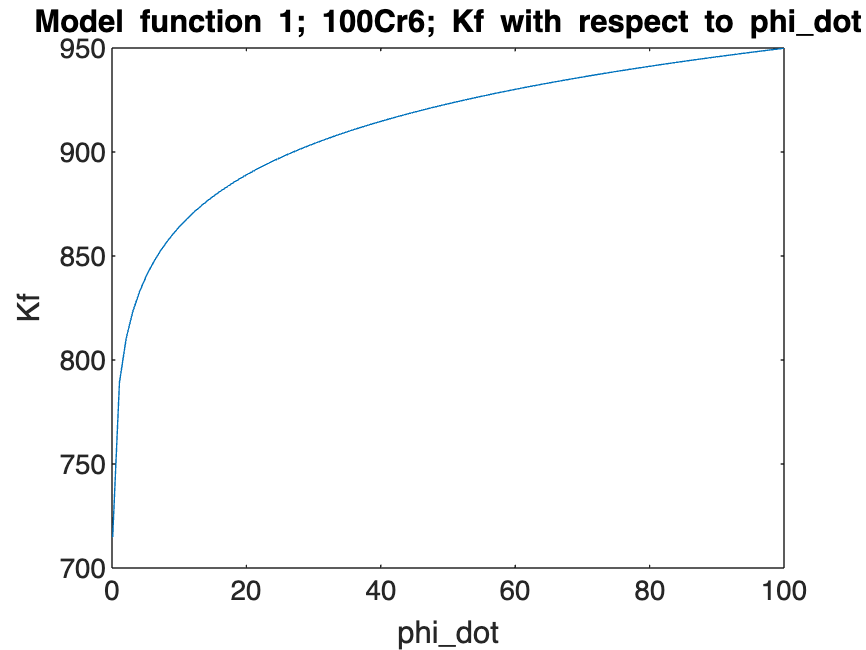

plot_model_1_2d(x06,Cr6)
title('Model function 1; 100Cr6; Kf with respect to phi\_dot')

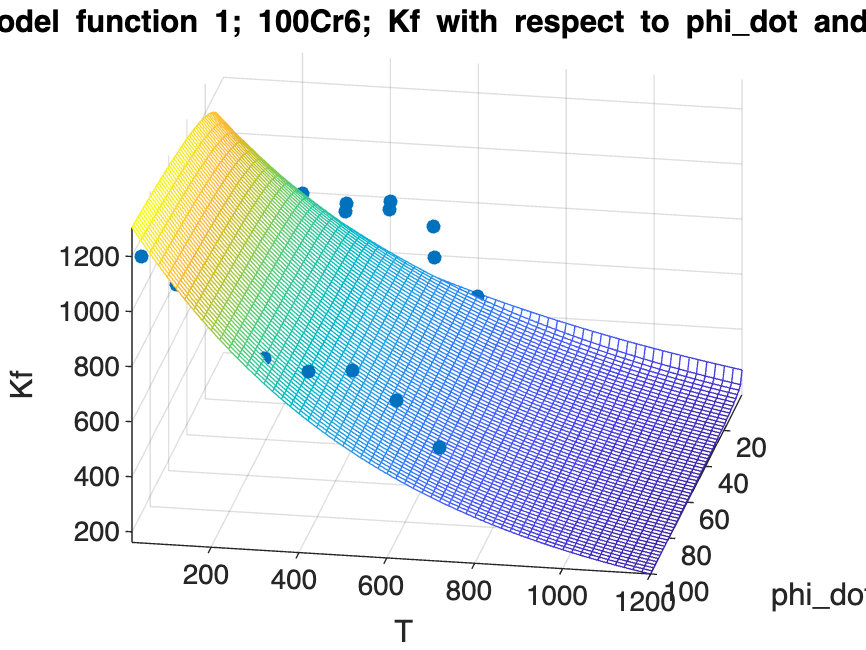

plot_mode_1_3d(x06,Cr6)
title('Model function 1; 100Cr6; Kf with respect to phi\_dot and T')

## Same thing for C15

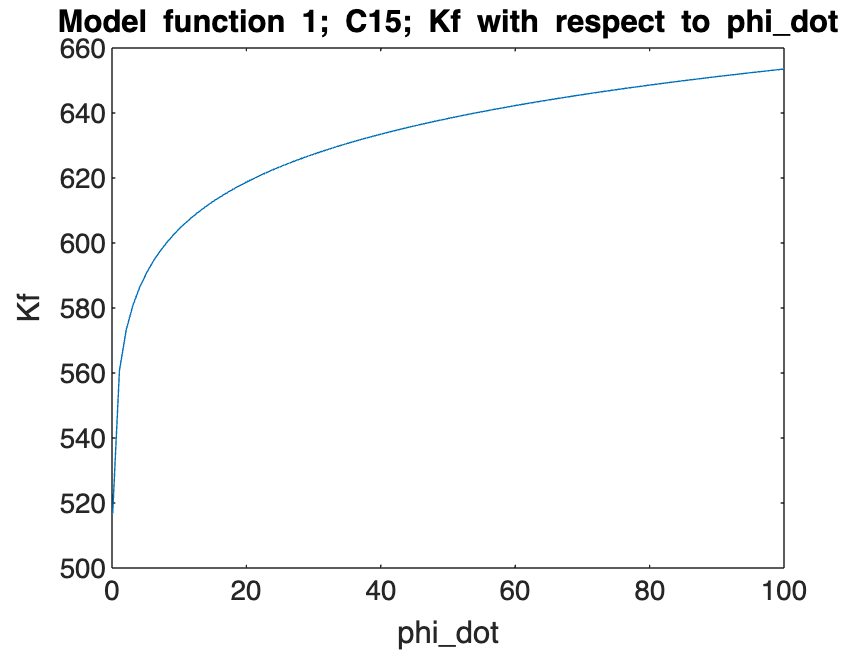

plot_model_1_2d(x15,C15)
title('Model function 1; C15; Kf with respect to phi\_dot')

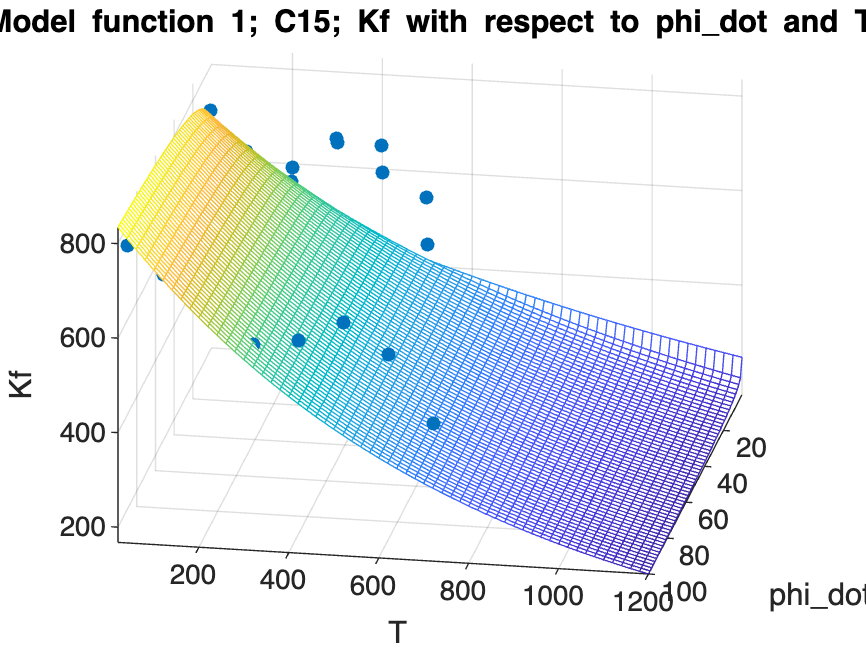

plot_mode_1_3d(x15,C15)
title('Model function 1; C15; Kf with respect to phi\_dot and T')

## Same thing for C60

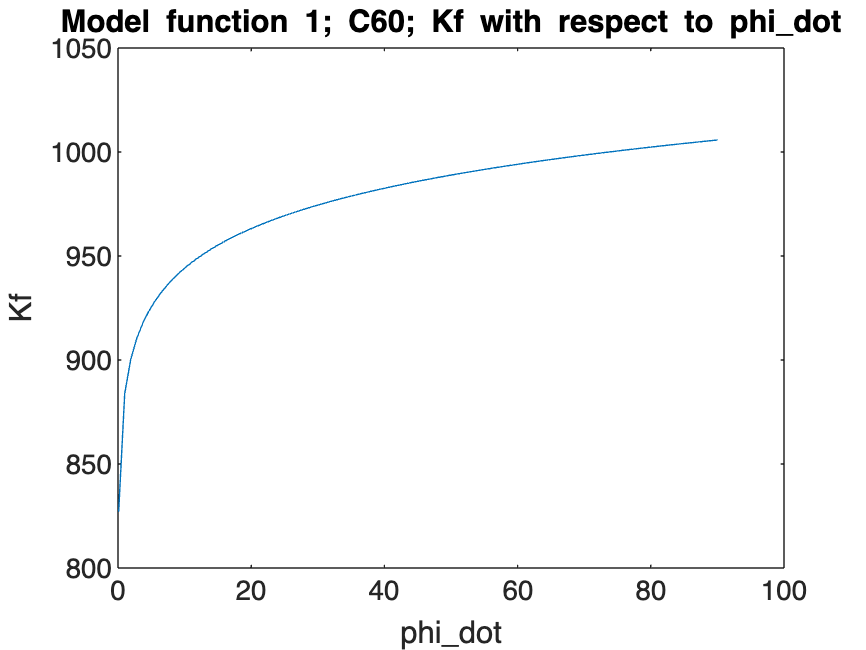

plot_model_1_2d(x60,C60)
title('Model function 1; C60; Kf with respect to phi\_dot')

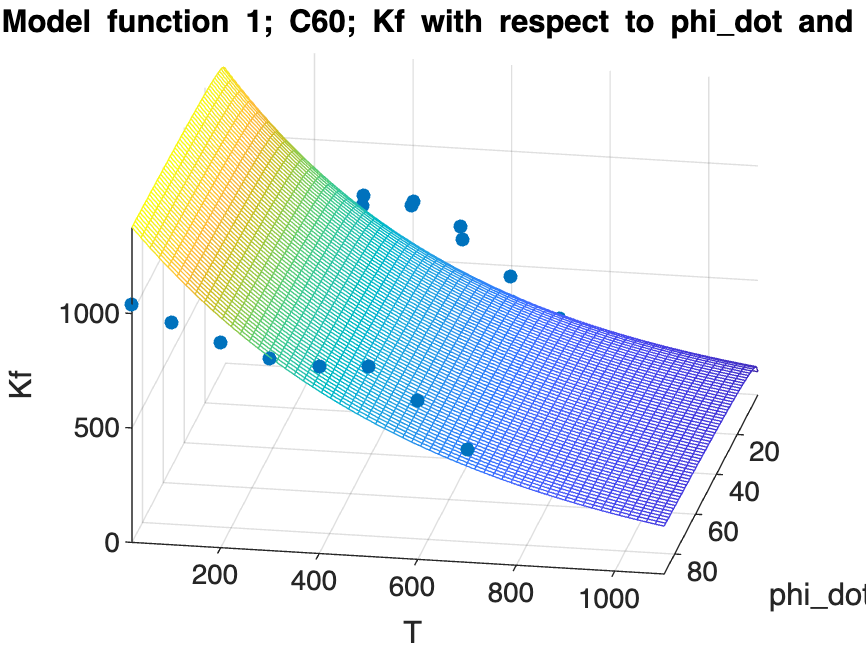

plot_mode_1_3d(x60,C60)
title('Model function 1; C60; Kf with respect to phi\_dot and T')

## Model 2 Function

## Creating matrixes with all the values we may later need

data06=[log(Cr6(:,1)) Cr6(:,1) log(Cr6(:,2)) Cr6(:,2) Cr6(:,3) log(Cr6(:,4))];
data15=[log(C15(:,1)) C15(:,1) log(C15(:,2)) C15(:,2) C15(:,3) log(C15(:,4))];
data60=[log(C60(:,1)) C60(:,1) log(C60(:,2)) C60(:,2) C60(:,3) log(C60(:,4))];

## Getting our vectors of unknown parameters

z06=model_func_2(data06)

z06 =    -0.0016
    0.0820
    0.2586
   -0.0297
   -0.0001
   -0.0521
   -0.0003
    0.0008
    0.0010
    7.2278


z15=model_func_2(data15)

z15 =    -0.0015
    0.0679
    0.3055
    0.0651
   -0.0001
   -0.0119
   -0.0004
    0.0005
   -0.0003
    6.8724


z60=model_func_2(data60)

z60 =    -0.0022
   -0.0457
    0.3557
   -0.5538
    0.0001
    0.0085
   -0.0002
   -0.0000
    0.0036
    7.6979


## Displaying the best fitting curves for the three functions

sprintf('Best fitting curve for 100Cr6 using model function 2: y=%f*e^(%f*T)*phi_dot^(%f+%fT+%fphi)*phi^(%f+%fT+%fphi_dot)*e^(%fphi+%fphi_dot)',exp(z06(10)),z06(1),z06(2),z06(5),z06(6),z06(3),z06(7),z06(8),z06(4),z06(9))

ans = 'Best fitting curve for 100Cr6 using model function 2: y=1377.226561*e^(-0.001593*T)*phi_dot^(0.082002+-0.000105T+-0.052111phi)*phi^(0.258644+-0.000258T+0.000830phi_dot)*e^(-0.029658phi+0.000957phi_dot)'

sprintf('Best fitting curve for C15 using model function 2: y=%f*e^(%f*T)*phi_dot^(%f+%fT+%fphi)*phi^(%f+%fT+%fphi_dot)*e^(%fphi+%fphi_dot)',exp(z15(10)),z15(1),z15(2),z15(5),z15(6),z15(3),z15(7),z15(8),z15(4),z15(9))

ans = 'Best fitting curve for C15 using model function 2: y=965.231734*e^(-0.001481*T)*phi_dot^(0.067929+-0.000086T+-0.011947phi)*phi^(0.305504+-0.000428T+0.000504phi_dot)*e^(0.065144phi+-0.000311phi_dot)'

sprintf('Best fitting curve for C60 using model function 2: y=%f*e^(%f*T)*phi_dot^(%f+%fT+%fphi)*phi^(%f+%fT+%fphi_dot)*e^(%fphi+%fphi_dot)',exp(z60(10)),z60(1),z60(2),z60(5),z60(6),z60(3),z60(7),z60(8),z60(4),z60(9))

ans = 'Best fitting curve for C60 using model function 2: y=2203.671363*e^(-0.002240*T)*phi_dot^(-0.045741+0.000101T+0.008467phi)*phi^(0.355744+-0.000174T+-0.000021phi_dot)*e^(-0.553828phi+0.003597phi_dot)'

## R^2 calculation

R2_06=R_square_model_2(data06,z06)

R2_06 = 0.6255

R2_15=R_square_model_2(data15,z15)

R2_15 = 0.4754

R2_60=R_square_model_2(data60,z60)

R2_60 = 0.9082

## Plotting the function for 100Cr6 keeping all variables constant except phi for 2D case and phi dot for 3D case. We choose to take the 253th measurement for that.

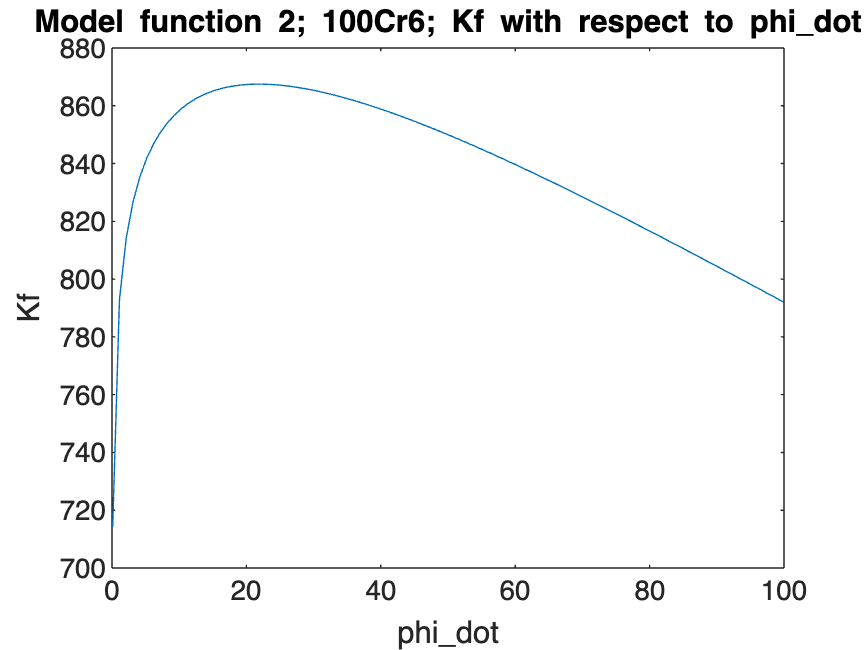

plot_model_2_2d(z06,Cr6)
title('Model function 2; 100Cr6; Kf with respect to phi\_dot')

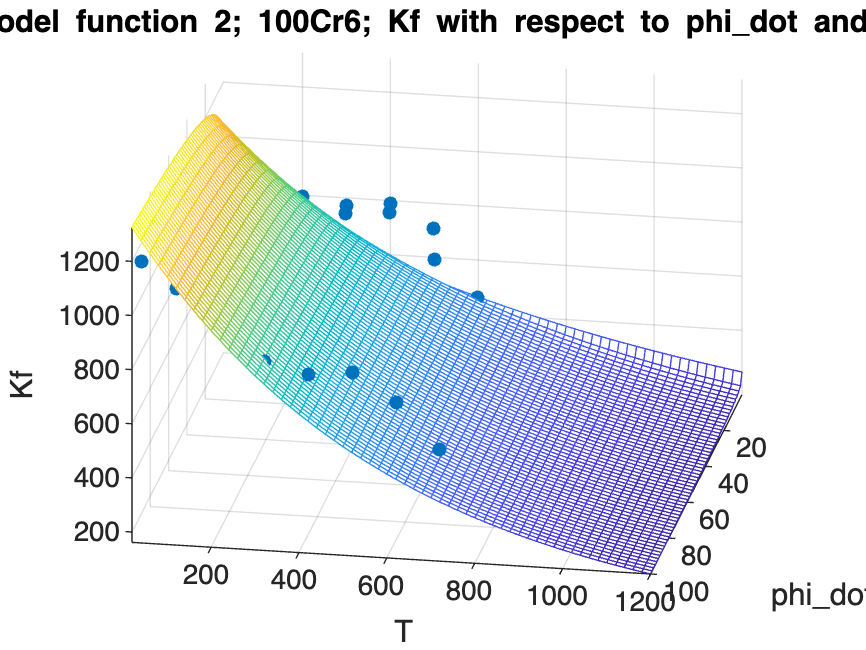

plot_mode_2_3d(z06,Cr6)
title('Model function 2; 100Cr6; Kf with respect to phi\_dot and T')

## Same thing for C15

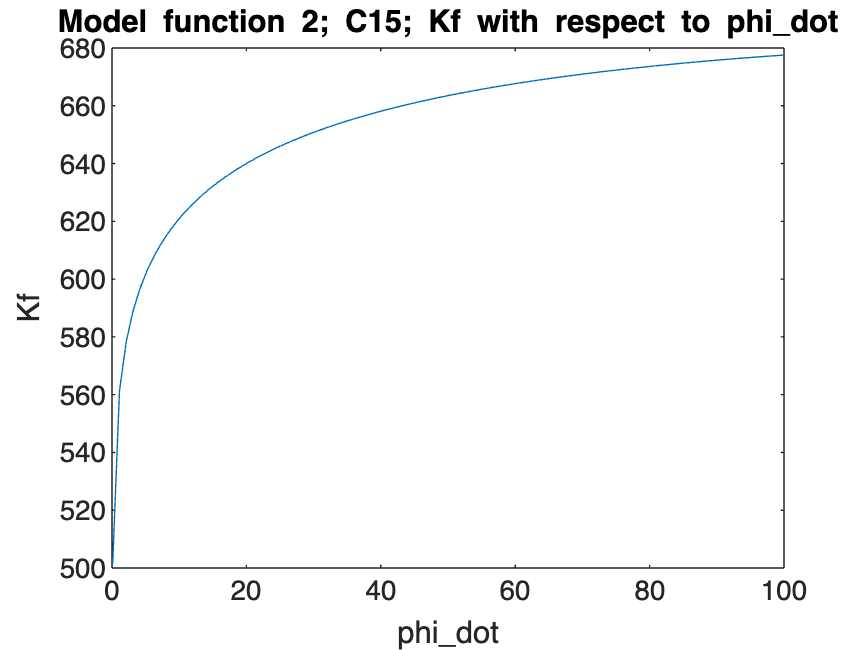

plot_model_2_2d(z15,C15)
title('Model function 2; C15; Kf with respect to phi\_dot')

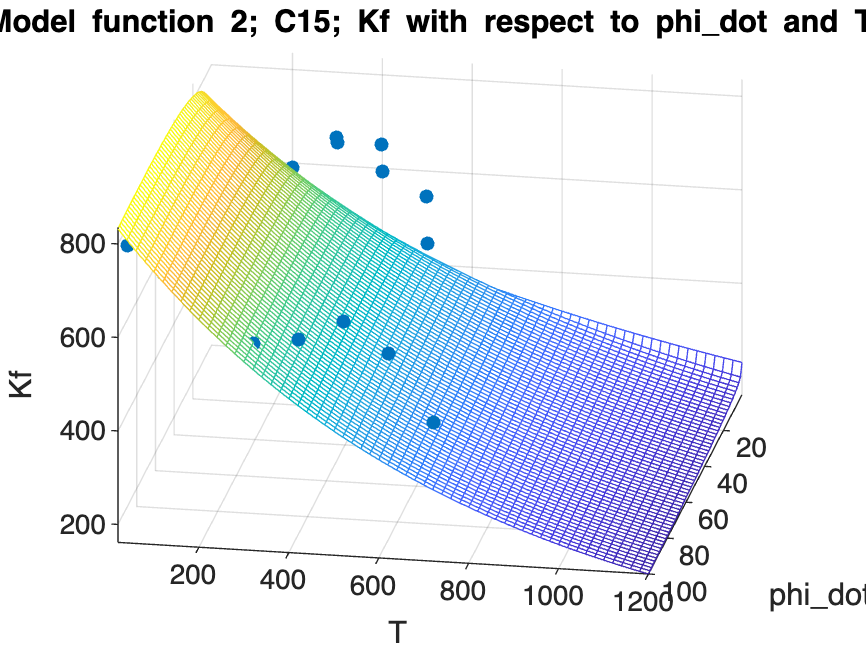

plot_mode_2_3d(z15,C15)
title('Model function 2; C15; Kf with respect to phi\_dot and T')

## Same thing for C60

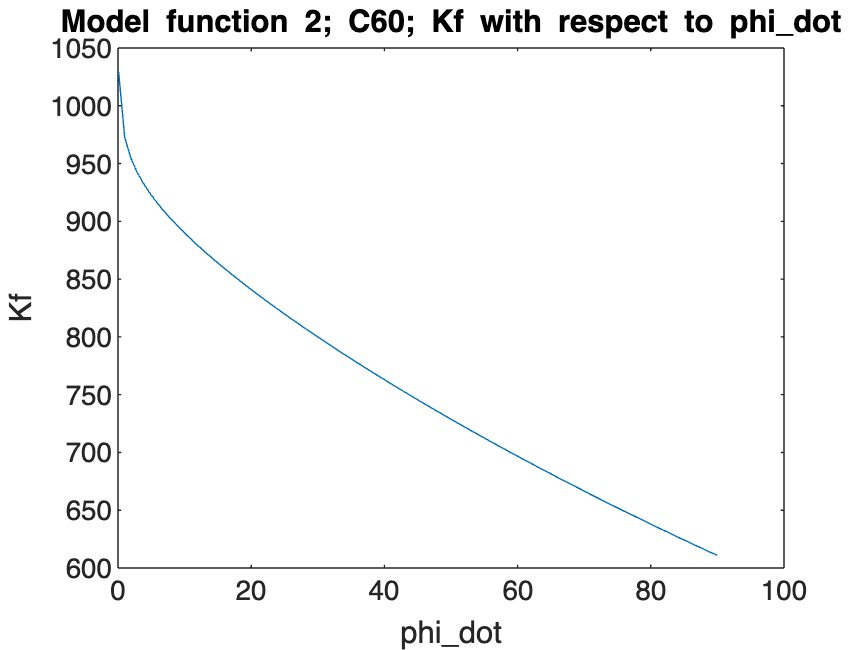

plot_model_2_2d(z60,C60)
title('Model function 2; C60; Kf with respect to phi\_dot')

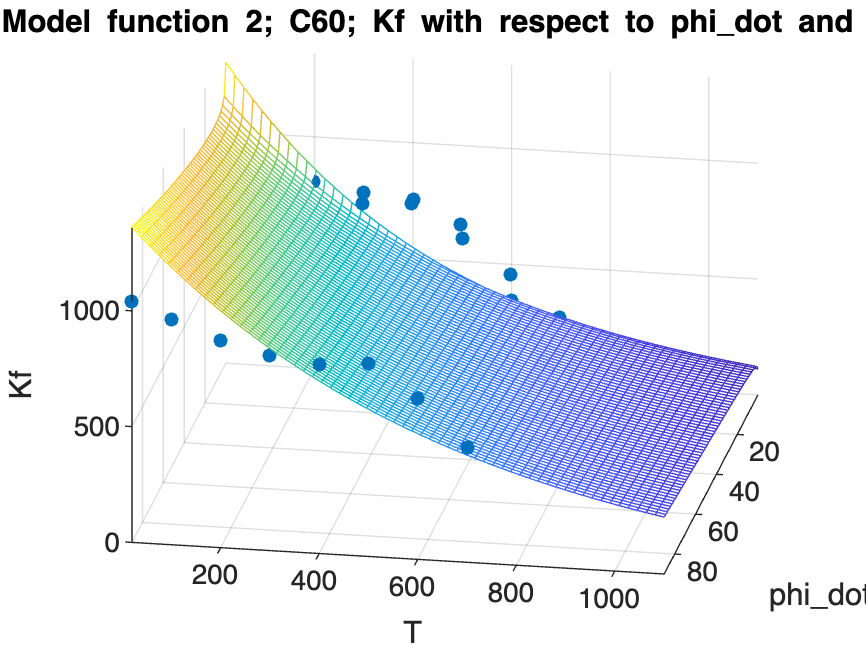

plot_mode_2_3d(z60,C60)
title('Model function 2; C60; Kf with respect to phi\_dot and T')

## Plotting predicted values vs measured ones for 100cr6

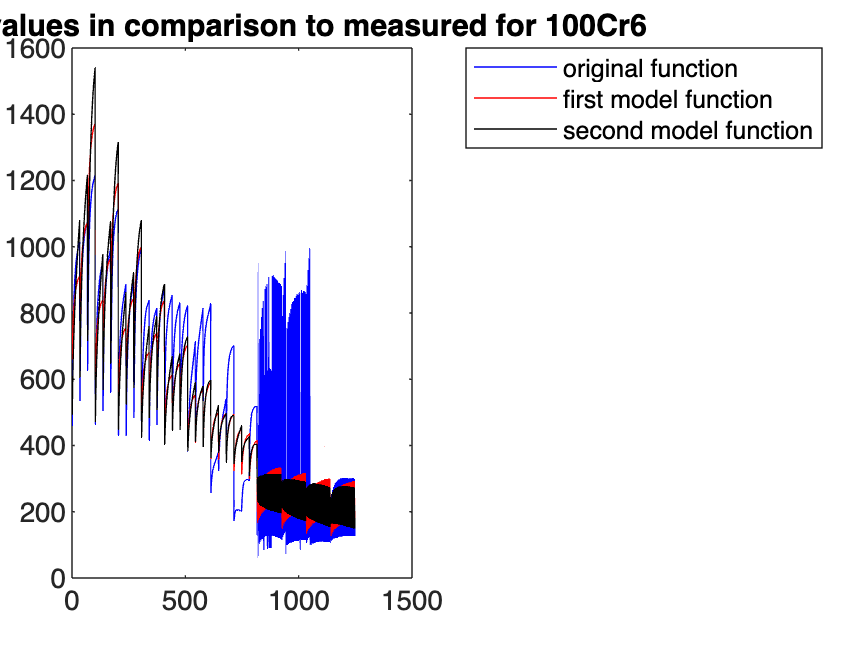

plot(Cr6(:,4),'b')
hold on
p06 = exp(x06(6)) .* exp(x06(1) .* Cr6(:,3)) .* Cr6(:,1).^(x06(2) + x06(5) .* Cr6(:,3)) .* Cr6(:,2).^x06(3) .* exp(x06(4) .* Cr6(:,2));
plot(p06, 'r')
hold on
f06 = exp(z06(10)) .* exp(z06(1) .* Cr6(:,3)) .* Cr6(:,1).^(z06(2) + z06(5) .* Cr6(:,3) + z06(6) .* Cr6(:,2)) .* Cr6(:,2).^(z06(3) + z06(7) .* Cr6(:,3) + z06(8) .* Cr6(:,1)) .* exp(z06(4) .* Cr6(:,2) + z06(9) .* Cr6(:,1));
plot(f06, 'k')
title('Predicted values in comparison to measured for 100Cr6')
legend('original function', 'first model function', 'second model function')
hold off

## Plotting predicted values vs measured ones for C15

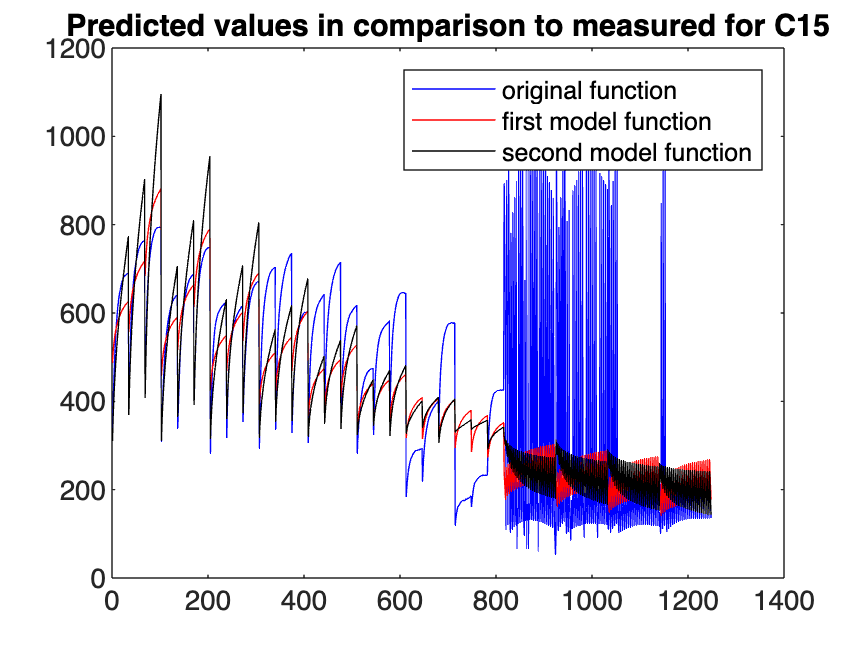

plot(C15(:,4), 'b')
hold on
p15 = exp(x15(6)) .* exp(x15(1) .* C15(:,3)) .* C15(:,1).^(x15(2) + x15(5) .* C15(:,3)) .* C15(:,2).^x15(3) .* exp(x15(4) .* C15(:,2));
plot(p15, 'r')
hold on
f15 = exp(z15(10)) .* exp(z15(1) .* C15(:,3)) .* C15(:,1).^(z15(2) + z15(5) .* C15(:,3) + z15(6) .* C15(:,2)) .* C15(:,2).^(z15(3) + z15(7) .* C15(:,3) + z15(8) .* C15(:,1)) .* exp(z15(4) .* C15(:,2) + z15(9) .* C15(:,1));
plot(f15, 'k')
title('Predicted values in comparison to measured for C15')
legend('original function', 'first model function', 'second model function')
hold off

## Plotting predicted values vs measured ones for C60

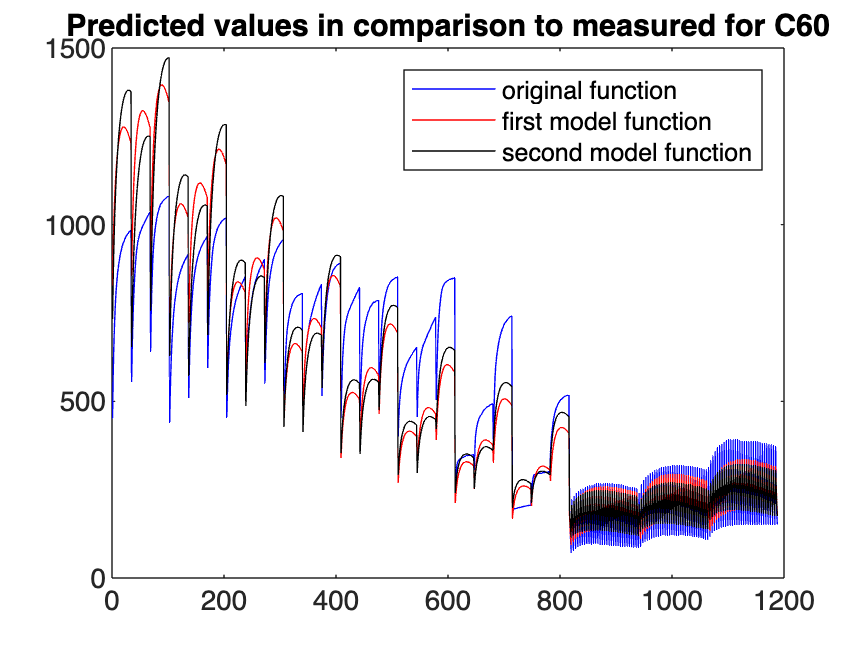

plot(C60(:,4), 'b')
hold on
p60 = exp(x60(6)) .* exp(x60(1) .* C60(:,3)) .* C60(:,1).^(x60(2) + x60(5) .* C60(:,3)) .* C60(:,2).^x60(3) .* exp(x60(4) .* C60(:,2));
plot(p60, 'r')
hold on
f60 = exp(z60(10)) .* exp(z60(1) .* C60(:,3)) .* C60(:,1).^(z60(2) + z60(5) .* C60(:,3) + z60(6) .* C60(:,2)) .* C60(:,2).^(z60(3) + z60(7) .* C60(:,3) + z60(8) .* C60(:,1)) .* exp(z60(4) .* C60(:,2) + z60(9) .* C60(:,1));
plot(f60, 'k')
title('Predicted values in comparison to measured for C60')
legend('original function', 'first model function', 'second model function')
hold off